**Transmural analysis using fabricated data**

**Nodes: 5x5**

**Slices: 2**

**Read in data from slices**

warning off
clear all
close all
clc
addpath(genpath('..'));

[nodes1, size] = parseSlice('3dFab_1.txt');
[nodes2] = parseSlice('3dFab_2.txt');

**Generate Fourier Coefficients**

tic
% Determine Fourier coefficients for each node
fs_order = 6;
for node_num = 1:length(nodes1)
    node_obj1 = nodes1(node_num);    
    node_obj1 = node_obj1.Normalize;
    node_obj1 = node_obj1.GenerateFourier(fs_order);
    node_obj1 = node_obj1.GenerateTensors;
    nodes1(node_num) = node_obj1;
    
    node_obj2 = nodes2(node_num);    
    node_obj2 = node_obj2.Normalize;
    node_obj2 = node_obj2.GenerateFourier(fs_order);
    node_obj2 = node_obj2.GenerateTensors;
    nodes2(node_num) = node_obj2;
end
toc

Elapsed time is 8.117958 seconds.


**Test Node**

node_O = nodes2(1);

**Inspect Fits**

gamma_Ffit = evalFourier(node_O.an, node_O.bn, 1, 1:360);
gamma_Ffit = gamma_Ffit/sum(gamma_Ffit);
tic
gamma_STFit = evalGammaST(node_O.D,1:360);
gamma_STFit = gamma_STFit/sum(gamma_STFit);
toc

Elapsed time is 61.353257 seconds.


D_ij = node_O.D{1};  
[v, d] = eig(D_ij);
theta1 = atan(v(2,1)/v(1,1)) * (180/pi) + 90;
theta2 = atan(v(2,2)/v(1,2)) * (180/pi) + 90;

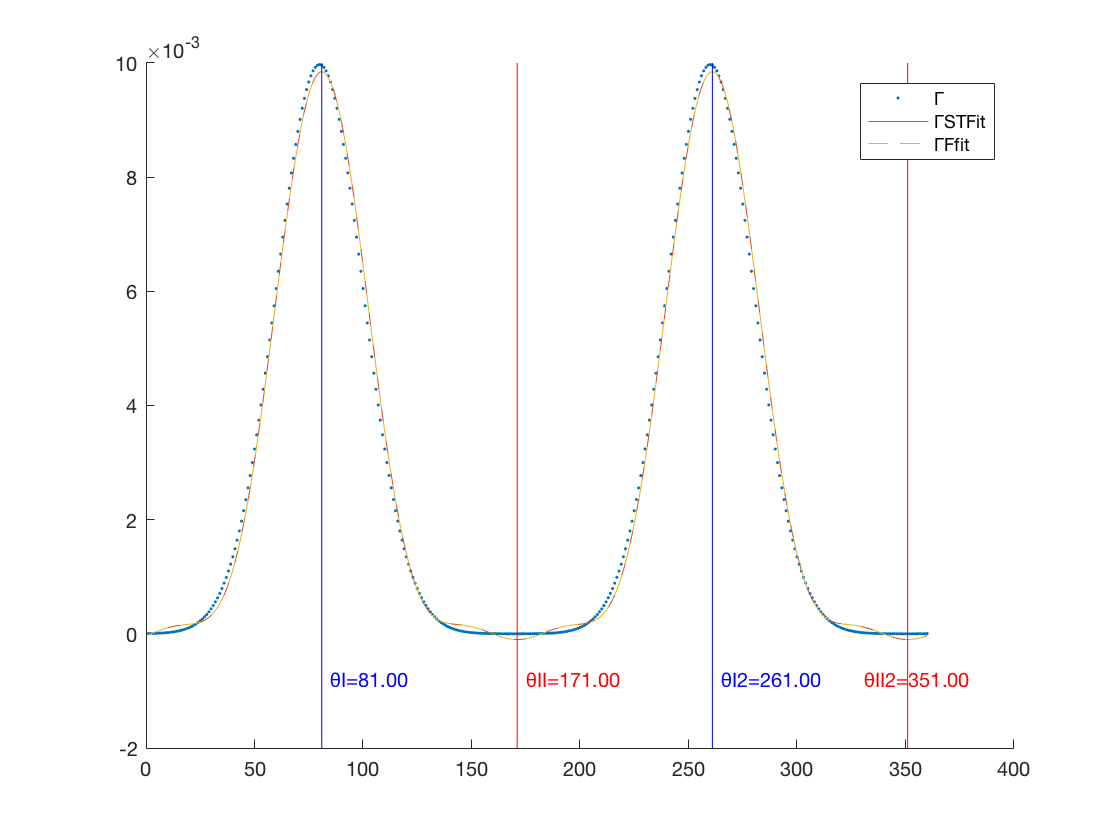

figure
hold on
plot(1:360, node_O.odf,'.'); plot(1:360,gamma_STFit);  plot(1:360,gamma_Ffit,'--') 
vline(theta1,'b', sprintf('θI=%.2f',theta1)); vline(theta1+180,'b', sprintf('θI2=%.2f',theta1+180)); 
vline(theta2,'r', sprintf('θII=%.2f',theta2)); vline(theta2+180,'r', sprintf('θII2=%.2f',theta2+180)); 
legend('show','Γ','ΓSTFit','ΓFfit')
hold off

**Tranformation**

Raw data is shifted according to the rotation angle.

x', y' pairs are computed from multiplication of the original position vector with the transformation matrix.

tx = 0; %% mm to the right
ty = 0;  %% mm up
theta = 45;
T = [cosd(theta) sind(theta) tx;
    -sind(theta) cosd(theta) ty; % Tranformation matrix from registration
    0 0 1];
    

node_R = nodes2(1);
tic
node_R = node_R.ApplyTransformation2(T);
toc

Elapsed time is 66.714776 seconds.


**Inspect post-rotation fits**

gamma_FfitR = evalFourier(node_R.an, node_R.bn, 1, 1:360);
gamma_FfitR = gamma_FfitR/sum(gamma_FfitR);

D_ij = [node_R.an(1) node_R.bn(1); node_R.bn(1) -node_R.an(1)];
[v, d] = eig(D_ij);
theta1 = atan(v(2,1)/v(1,1)) * (180/pi) + 90

theta1 = 81.0001

theta2 = atan(v(2,2)/v(1,2)) * (180/pi) + 90;

D_ij = node_R.D{1};  
[v, d] = eig(D_ij);
theta1 = atan(v(2,1)/v(1,1)) * (180/pi) + 90

theta1 = 36.0001

theta2 = atan(v(2,2)/v(1,2)) * (180/pi) + 90;

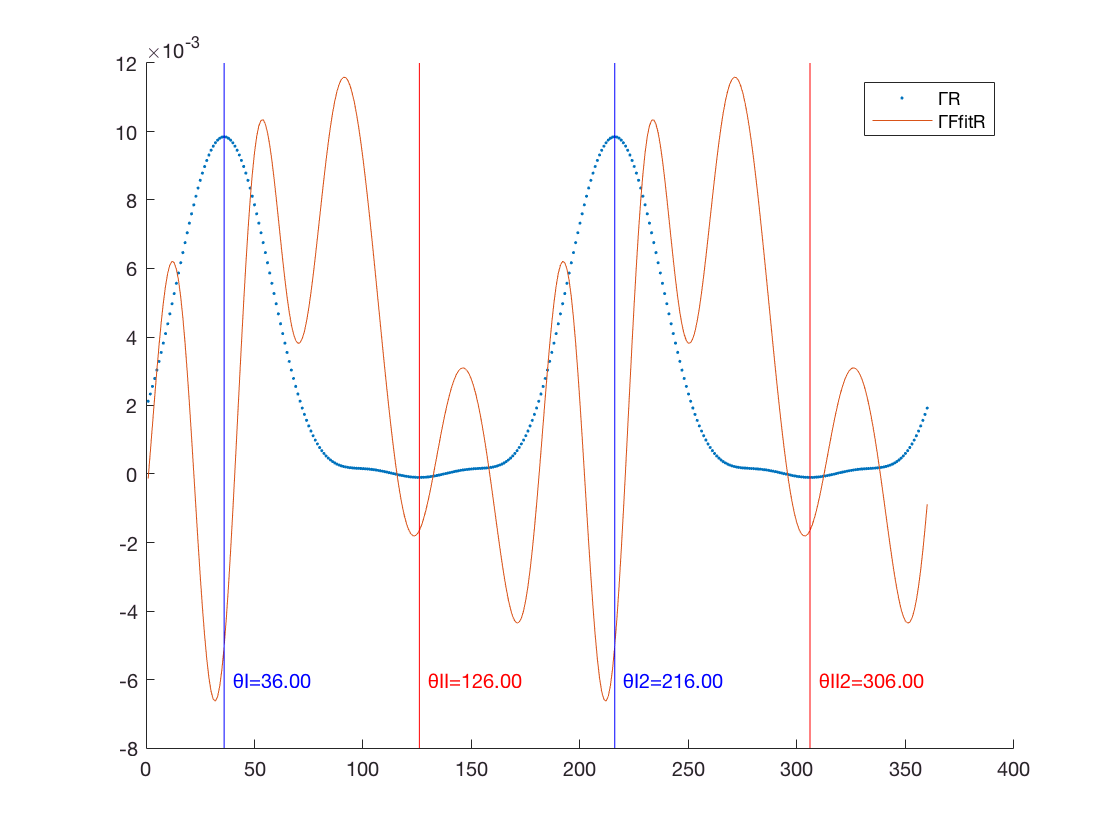

figure
hold on
plot(1:360, node_R.odf,'.'); plot(1:360,gamma_FfitR) 
vline(theta1,'b', sprintf('θI=%.2f',theta1)); vline(theta1+180,'b', sprintf('θI2=%.2f',theta1+180)); 
vline(theta2,'r', sprintf('θII=%.2f',theta2)); vline(theta2+180,'r', sprintf('θII2=%.2f',theta2+180)); 
legend('show','ΓR','ΓFfitR')
hold off

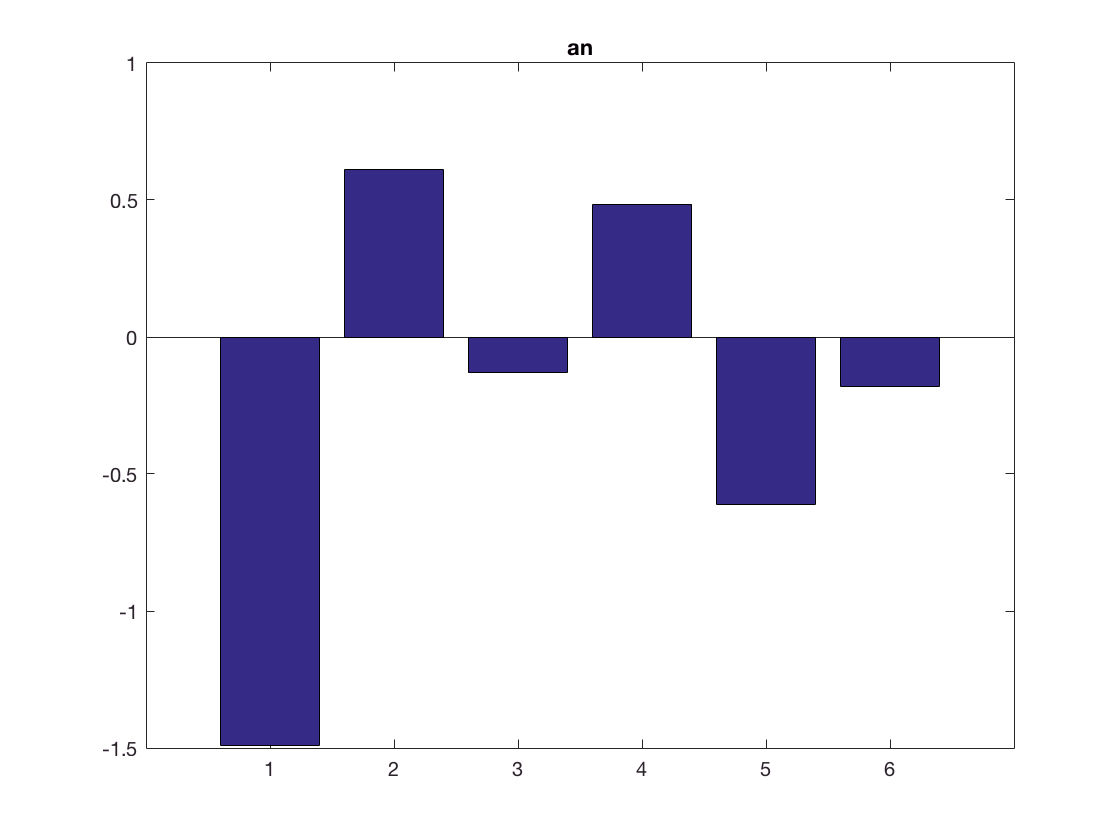


bar(node_R.an); title('an');

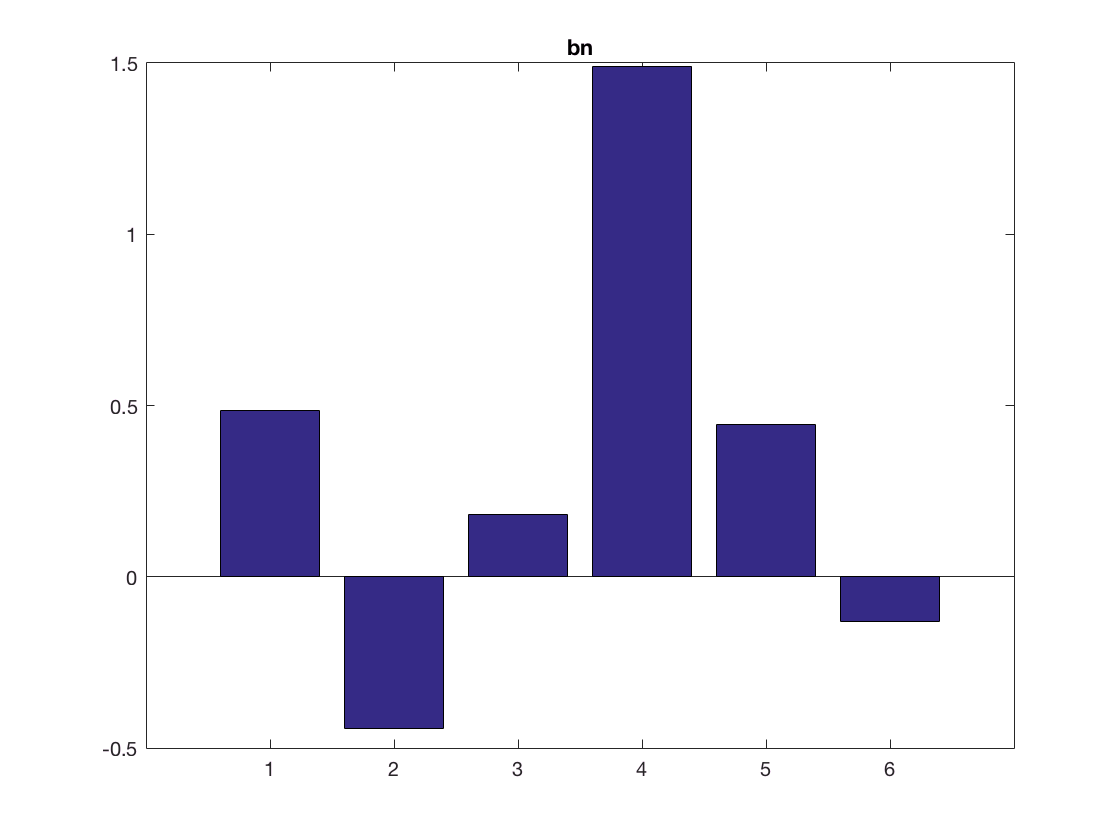

bar(node_R.bn); title('bn');

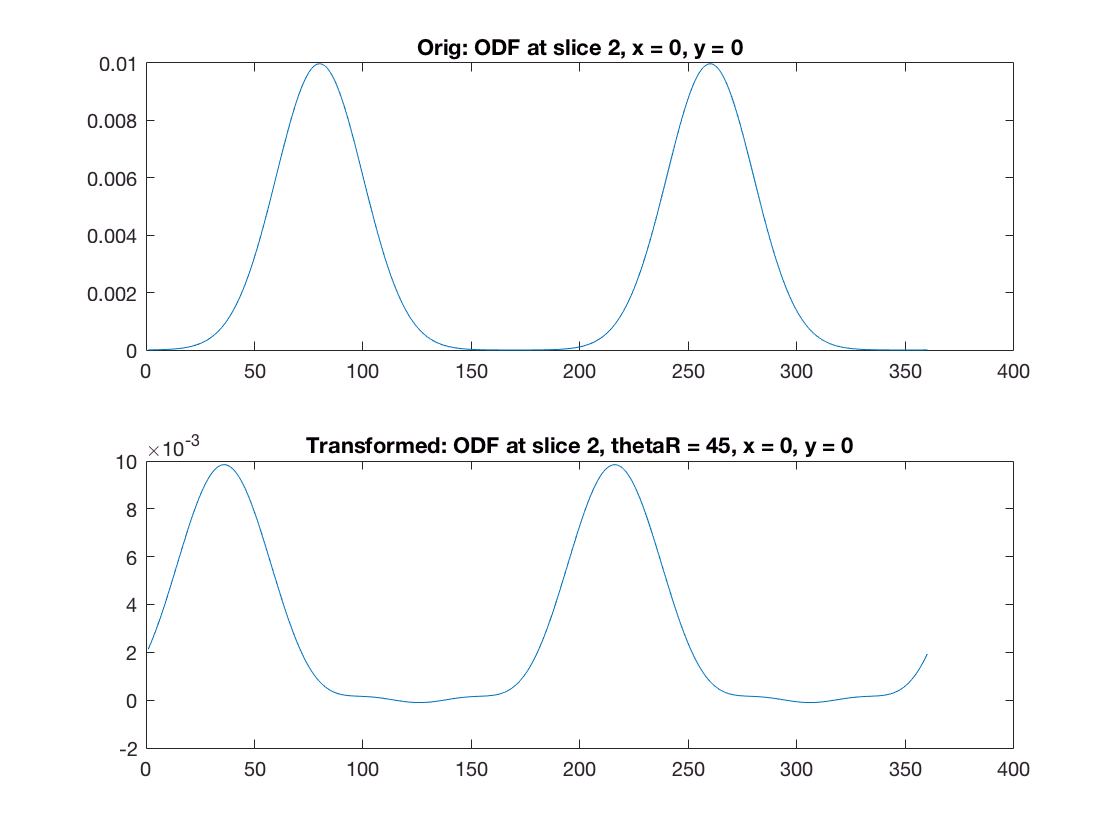

figure
subplot(2,1,1)
plot(node_O.odf)
title(sprintf('Orig: ODF at slice 2, x = %d, y = %d', node_O.x, node_O.y));
subplot(2,1,2) 
plot(node_R.odf)
title(sprintf('Transformed: ODF at slice 2, thetaR = %d, x = %d, y = %d', theta, node_R.x, node_R.y));

**Interpolating**

An interpolation surface is created for each fourier coefficient, bit value and x,y point for a slice. 

The surface contains all triplets (x, y, value) where *value* is the fourier coefficient or bit values.

The result of the interpolation is the *value* of the surface at points x', y'

**Set up grid**

x = [nodes1(:).x];
y = [nodes1(:).y];
step_size =  nodes1(2).x - nodes1(1).x;
[X1, X2] = ndgrid(0.0:step_size:x(end) , 0:step_size:y(end));

**New Node Position**

x_prime = 1.5;
y_prime = 1.5;

**Interpolation step to find values for each coefficient**

an_prime = [];
for i = 1:fs_order % for each coeff
   f = [];
   for j = 1:prod(size) % for each node
       f(j) = nodes1(j).an(i)
   end

   f_r = reshape(f, [5,5]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   an_prime(i) = F_interp(x_prime, y_prime);
end

f = -1.4907

f =    -1.4907   -0.8311


f =    -1.4907   -0.8311   -1.2353


f =    -1.4907   -0.8311   -1.2353   -1.4907


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049    0.6264


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049    0.6264    0.9042


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049    0.6264    0.9042    0.4241


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049    0.6264    0.9042    0.4241   -0.1122


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049    0.6264    0.9042    0.4241   -0.1122   -0.6383


f =    -1.4907   -0.8311   -1.2353   -1.4907   -1.5674   -1.5436   -1.3575   -1.0078   -0.5371   -0.0036    0.3193   -0.2204   -0.7365   -1.1650   -1.4533   -1.2995   -0.9216   -0.4334    0.1049    0.6264    0.9042    0.4241   -0.1122   -0.6383   -1.0890


f = 0.6104

f =     0.6104   -0.3312


f =     0.6104   -0.3312    0.1824


f =     0.6104   -0.3312    0.1824    0.6104


f =     0.6104   -0.3312    0.1824    0.6104    0.7545


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516   -0.5159


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516   -0.5159   -0.2502


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516   -0.5159   -0.2502   -0.6478


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516   -0.5159   -0.2502   -0.6478   -0.7500


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516   -0.5159   -0.2502   -0.6478   -0.7500   -0.5057


f =     0.6104   -0.3312    0.1824    0.6104    0.7545    0.7090    0.3772   -0.1313   -0.5790   -0.7581   -0.6958   -0.7275   -0.4225    0.0787    0.5427    0.2826   -0.2335   -0.6412   -0.7516   -0.5159   -0.2502   -0.6478   -0.7500   -0.5057   -0.0265


f = -0.1312

f =    -0.1312    0.2214


f =    -0.1312    0.2214    0.0907


f =    -0.1312    0.2214    0.0907   -0.1312


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508   -0.2232


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508   -0.2232   -0.2292


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508   -0.2232   -0.2292   -0.1736


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508   -0.2232   -0.2292   -0.1736    0.0436


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508   -0.2232   -0.2292   -0.1736    0.0436    0.2114


f =    -0.1312    0.2214    0.0907   -0.1312   -0.2231   -0.1932   -0.0000    0.1930    0.1922   -0.0035   -0.1377    0.0885    0.2213    0.1310   -0.0908    0.0463    0.2119    0.1645   -0.0508   -0.2232   -0.2292   -0.1736    0.0436    0.2114    0.1656


Index exceeds matrix dimensions.



bn_prime = [];
for i = 1:(fs_order) % for each coeff
   f = [];
   for j = 1:prod(size) % for each node
       f(j) = nodes1(j).an(i);
   end

   f_r = reshape(f, [5,5]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   bn_prime(i) = F_interp(x_prime, y_prime);
end

figure 
C_grid = reshape(f_r, [5,5]);
mesh(X1,X2,C_grid);

hold on

plot3(x_prime,y_prime,bn_prime(end),'*','MarkerSize',100);

title('Interpolation Grid for coefficient C')
hold off

% Gen data from for plotting
d = evalFourier(an_prime, bn_prime, 1, 1:360);
figure
plot(d)
title(sprintf('Post-interpolated ODF for node at x=%d,y=%d', x_prime, y_prime));
